# Identifying a 2D SSM for an oscillator chain

This is an example of how to reconstruct a slow 2D SSM of a mechanical system using synthetic measurements of the full state space. In this example, we consider a damped oscillator chain with an additional nonlinear spring attached to the leftmost mass. The measurements for this example are transients occurring from exact initial conditions on the slow 2D SSM.

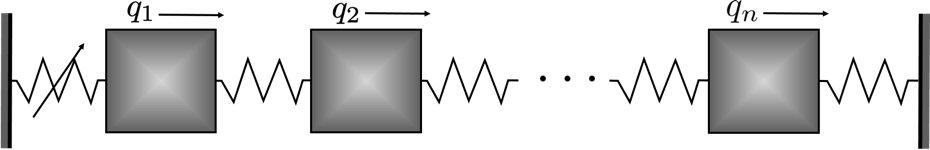

clearvars
close all

## Example setup

The $N$-degree of freedom dynamical system is of the form


$$\mathbf{M\ddot{q}} + \mathbf{C\dot{q}} + \mathbf{Kq} + \mathbf{f}(\mathbf{q},\mathbf{\dot{q}}) 
= \mathbf{0}$$


where $\mathbf{f}=\mathcal{O}(|\mathbf{q}|^2,|\mathbf{\dot{q}}|^2,|\mathbf{q}||\mathbf{\dot{q}}|)$ represents the nonlinearities and $\mathbf{M}$, $\mathbf{C}$, and $\mathbf{K}$ are the $n\times n$ mass, stiffness, and damping matrices, respectively.

We rewrite the system in first-order form as


$$\mathbf{\dot{y}} = \mathbf{A}\mathbf{y} + \mathbf{G}(\mathbf{y}) = \mathbf{F}(\mathbf{y})$$


with

$\mathbf{y}=\left[\begin{array}{c}\mathbf{q}\\\dot{\mathbf{q}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}\mathbf{0}  & \mathbf{I}\\-\mathbf{M}^{-1}\mathbf{K} & -\mathbf{M}^{-1}\mathbf{C} \end{array}\right],\quad\mathbf{G}(\mathbf{y})=\left[\begin{array}{c}  \mathbf{0} \\ -\mathbf{M}^{-1}\mathbf{f}(\mathbf{y})\end{array}\right]$.

n         = 5;      % number of masses
mass      = 1;
stiffness = 1;
damping   = 0.01;

M = mass*eye(n);
K = stiffness*(2*eye(n) - diag(ones(1,n-1),-1) - diag(ones(1,n-1),1));
C = damping*K;

% nonlinearities: f1 = 0.33*q1dot^2 + 2*q1^3 + 0.3*q1^2*q1dot + 0.5*q1dot^3
F2 = sptensor(zeros(n, 2*n, 2*n)); F3 = sptensor(zeros(n, 2*n, 2*n, 2*n));
F2(1,n+1,n+1) = 0.33;    % q1dot^2
F3(1,1,1,1) = 2;         % q1^3
F3(1,1,1,n+1) = 0.3;     % q1^2*q1dot 
F3(1,n+1,n+1,n+1) = 0.5; % q1dot^3
fnl = {F2, F3};

[F, lambda, E] = functionFromTensors(M, C, K, fnl);

## Generation of Synthetic Data

Having set up the dynamics of the problem, we now move on to generate synthetic data, which will be used to fit a parametrisation of the manifold. We will divide the data into a training set, for model fitting, and a test set, for validation.

nTraj = 3;
indTest = [1];
indTrain = setdiff(1:nTraj, indTest);

We now set the initial conditions for the trajectories, which are picked exactly on the slowest 2D SSM of the systems, computed using SSMTool.

ICRadius = 0.6;
IC = getSSMIC(M, C, K, fnl, nTraj, ICRadius, 2, 1);

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.588190e-03
modal damping ratio for 2 mode is 5.000000e-03
modal damping ratio for 3 mode is 7.071068e-03
modal damping ratio for 4 mode is 8.660254e-03
modal damping ratio for 5 mode is 9.659258e-03

 The first 10 eigenvalues are given as 
  -0.0013 + 0.5176i
  -0.0013 - 0.5176i
  -0.0050 + 1.0000i
  -0.0050 - 1.0000i
  -0.0100 + 1.4142i
  -0.0100 - 1.4142i
  -0.0150 + 1.7320i
  -0.0150 - 1.7320i
  -0.0187 + 1.9318i
  -0.0187 - 1.9318i

(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     3     1
     4     2
     5     3
     6     4
     0     2
     1     3
     2     4
     3     5
     4     6

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.0050 +

The data is generated by time-integration of the right-hand side of the system. In this case we are observing the full state space, so the `observable` function is the identity.

observable = @(x) x;
slowTime = 2*pi/abs(lambda(1));
nPeriods = 200; 
nDataPerPeriod = 50;
endTime = nPeriods * slowTime;
nSamp = nDataPerPeriod * nPeriods + 1;
dt = endTime/(nSamp-1);
tic
yData = integrateTrajectories(F, endTime, IC, nSamp, observable);

simulating trajectory 1 of 3...
simulating trajectory 2 of 3...
simulating trajectory 3 of 3...


toc

Elapsed time is 0.892518 seconds.


## Plot generated trajectory data

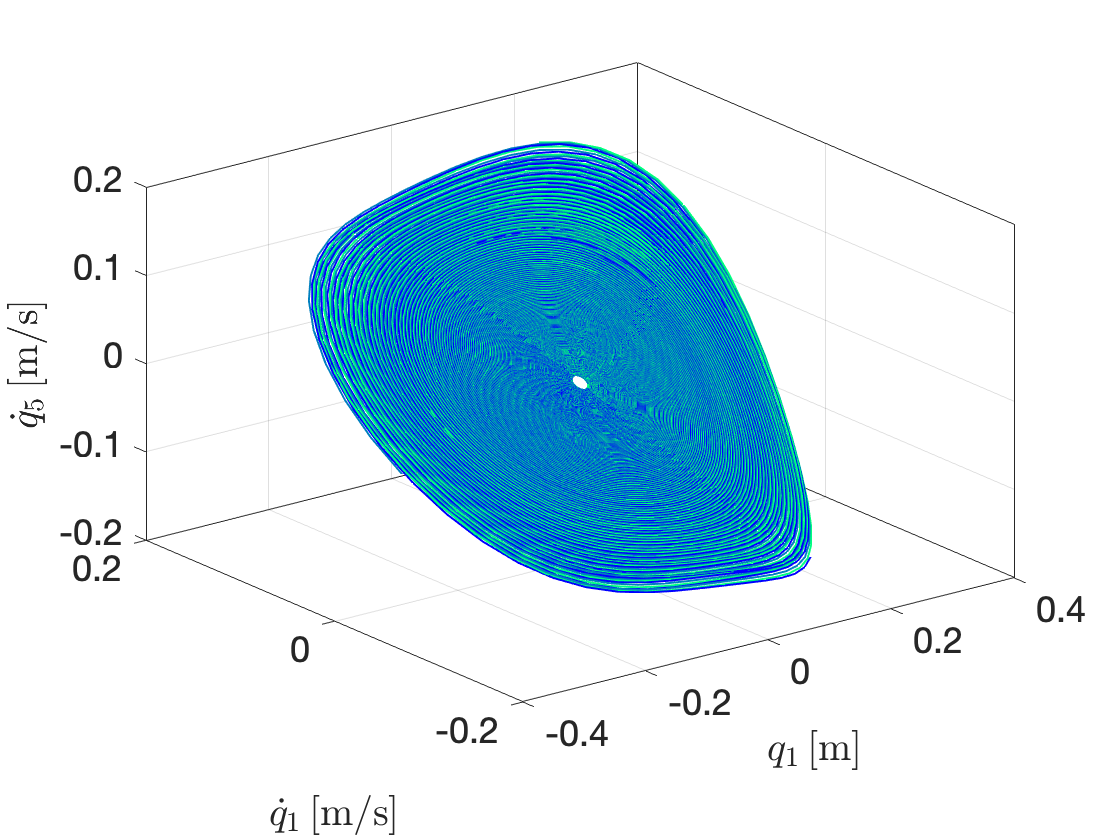

customFigure(); colororder(winter(nTraj));
for iTraj = 1:size(yData,1)
    plot3(yData{iTraj,2}(1,:), yData{iTraj,2}(n+1,:), yData{iTraj,2}(2*n,:),'Linewidth',1,'Displayname',['Trajectory ' num2str(iTraj)])
end
xlabel('$q_1 \, [$m$]$','Interpreter','latex'); 
ylabel('$\dot{q}_1 \, [$m/s$]$','Interpreter','latex'); 
zlabel(['$\dot{q}_{' num2str(n) '} \, [$m/s$]$'],'Interpreter','latex'); 
view(3)

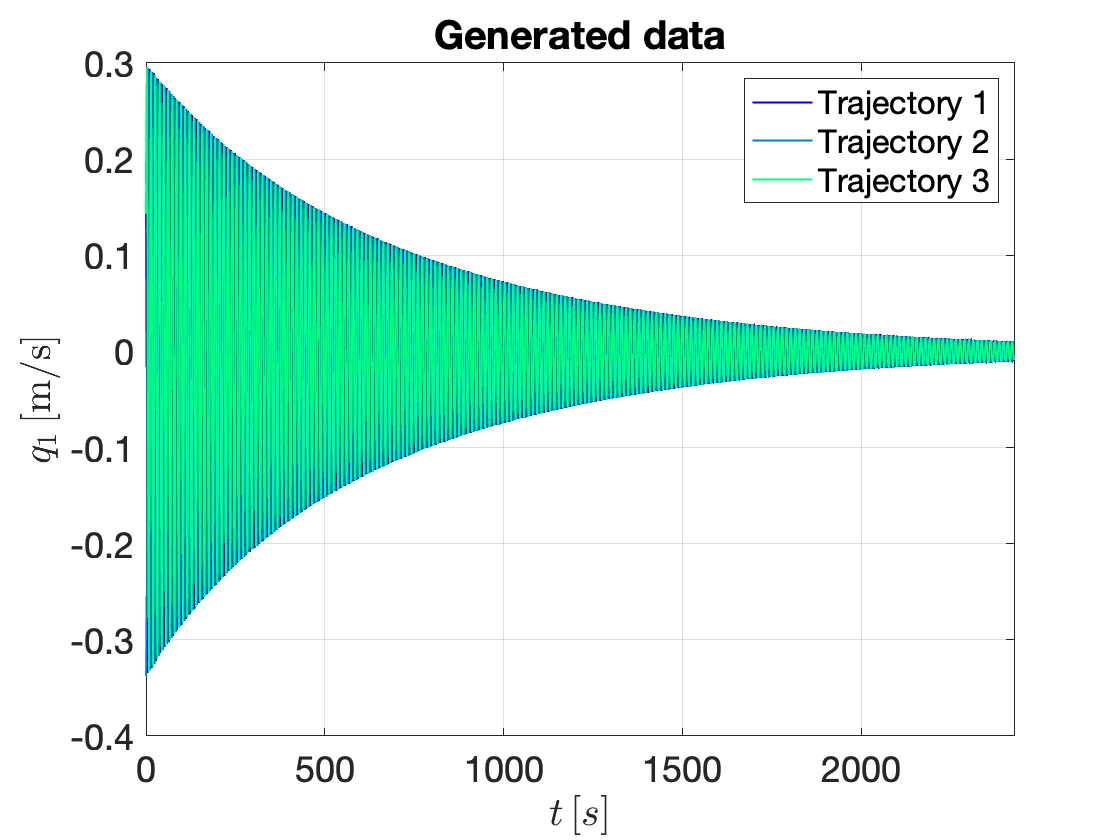



customFigure(); colororder(winter(nTraj));
for iTraj = 1:size(yData,1)
    plot(yData{iTraj,1}, yData{iTraj,2}(1,:),'Linewidth',1,'Displayname',['Trajectory ' num2str(iTraj)])
end
xlim([0 endTime])
xlabel('$t \, [s]$','Interpreter','latex'); 
ylabel('$q_1 \, [$m/s$]$','Interpreter','latex'); 
title('Generated data')
legend('location','NE')

## Datadriven manifold fitting

The measured trajectories are assumed to lie close to a two-dimensional manifold that is tangent at the origin to the eigenspace corresponding to the slowest pair of eigenvalues. We now want to fit a polynomial of order $M$ to the data points to approximate the manifold. Here we use a graph style parametrization, meaning that the manifold is parametrized using coordinates in the computed eigenspace $V_e$. 

We seek the $2n\times m_M$ polynomial coefficient matrix $H$ of the manifold on the form

$y = V_e V_e^\top y + H \phi_{m,2:M}(V_e^\top y) $,

where the function $\phi_{m,2:M}(q)$ computes a vector of all $m_M$ monomials from orders 2 up to $M$ of an $m$-vector $q$. This optimization problem amounts to minimizing a cost function computed from the measured data $y_k$,


$$C_r(V_e,H) = \sum_{k=1}^N ||y_k - V_eV_e^\top y_k - H\phi_{m,2:M}(V_e^\top 
y_k) ||$$


to find $H$ and the $2N\times 2$ eigenspace matrix $V_e$, under the constraints that $V_e^\top H=0$ and $V_e^\top V_e = I$. The minimization is performed with the Matlab routine `fmincon` in `IMGeometry`.

SSMOrder = 6; SSMDim = 2;
[IMInfo, SSMChart, SSMFunction] = IMGeometry(yData(indTrain,:), SSMDim, SSMOrder);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.559452e-07    6.661e-16    2.703e-05
    1       2    3.547506e-07    1.042e-09    2.656e-05    3.469e-05
    2       3    3.491376e-07    2.523e-08    2.424e-05    1.709e-04
    3       4    3.288906e-07    5.395e-07    1.361e-05    7.910e-04
    4       5    3.155231e-07    1.491e-06    1.531e-05    1.318e-03
    5       6    3.149242e-07    1.763e-09    1.542e-05    5.389e-05
    6       7    3.118029e-07    9.064e-09    1.506e-05    1.710e-04
    7       8    2.982144e-07    1.837e-07    1.293e-05    7.897e-04
    8       9    2.688260e-07    3.116e-06    1.000e-05    3.260e-03
    9      10    2.681058e-07    9.401e-08    4.626e-06    5.642e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function i

## Plot and validation

Now that we have computed the eigenspace of the manifold, we pass to the reduced coordinates $y$ by projecting all trajectories onto the eigenspace and plot the SSM. 

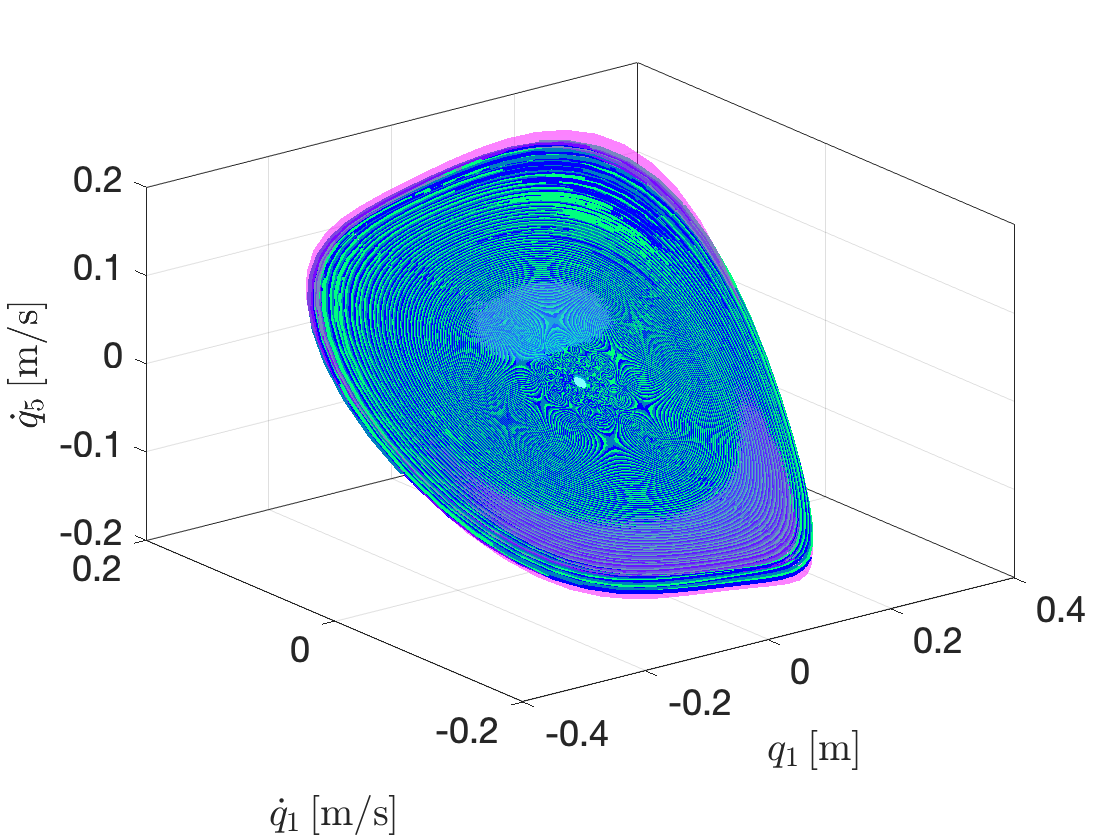

etaData = projectTrajectories(IMInfo, yData);

coordPlot = [1 n+1 2*n];
plotSSMWithTrajectories(IMInfo, coordPlot, yData,'Margin',5,'Colors', winter(nTraj));
xlabel('$q_1 \, [$m$]$','Interpreter','latex'); 
ylabel('$\dot{q}_1 \, [$m/s$]$','Interpreter','latex'); 
zlabel(['$\dot{q}_{' num2str(n) '} \, [$m/s$]$'],'Interpreter','latex'); 
view(3)

## Reduced order model

We compute a model for the reduced dynamics with the truncated training data projected onto the manifold. The function `IMDynamicsFlow` fits a polynomial map


$$\dot{\eta} = W_r \phi(\eta)$$


where $\phi(\eta)$ again computes a vector of all monomials of $\eta$, and  $W_r$ is a matrix of polynomial coefficients. 

We are also specifying that we want the reduced dynamics in normal form, so that the map $N$ will fulfill


$$\dot{z} = N(z) = Dz + W_n\phi(z)$$


with $D$ a diagonal matrix and $W_n$ coefficients for the near-resonant nonlinear terms, after a near-identity change of coordinates


$$z = T^{-1}(\eta) = \eta + W_t \phi(\eta)$$


with $W_t$ containing the coefficients for the nonlinear terms of the coordinate change. The polar normal form of the dynamics for this 2D SSM case has the form

$\dot{\rho} = c(\rho)\rho$ ,

$\dot{\theta} =  \omega(\rho)$ ,

which is identified from data using the function `IMDynamicsFlow` under the 'normalform' style.

Estimation of the reduced dynamics...  Done. 
Estimation of the reduced dynamics in normal form...
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1      6.85624e-06                      0.000115
     1           4      4.93956e-06             91       0.000101  
     2           5       2.0987e-06              1        7.2e-05  
     3           6      9.48803e-07              1       6.59e-05  
     4           7      3.43403e-07              1       4.94e-05  
     5           8      8.13576e-08              1       1.51e-05  
     6           9      4.90537e-08              1       4.38e-06  
     7          10      4.48339e-08              1        3.3e-06  
     8          11      4.15449e-08              1       2.25e-06  
     9          12      3.84432e-08              1        2.6e-06  
    10          13      3.72342e-08              1       1.17e-06  
    11          14

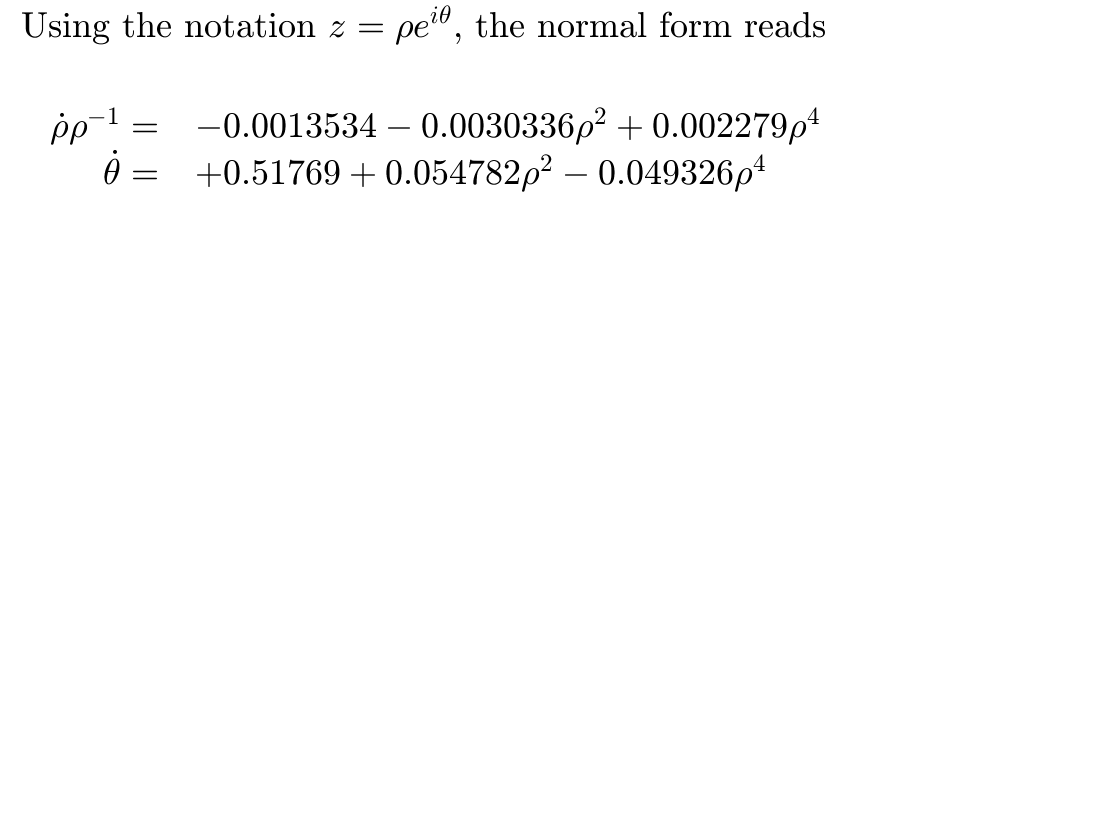

ROMOrder = 5;
RDInfo = IMDynamicsFlow(etaData(indTrain,:), 'R_PolyOrd', ROMOrder, 'style', 'normalform');

We transform the truncated initial condition of our test trajectory according to the obtained change of coordinates, and iterate our reduced order evolution rule to predict the development of the trajectory.

[yRec, etaRec, zRec] = advect(IMInfo, RDInfo, yData);

## Evaluation of reduced dynamics

The error RRMSE is computed as the average distance of the predicted trajectory to the measured one in the full state space. We also plot the testing trajectory.

% Compute errors
normedTrajDist = computeTrajectoryErrors(yRec, yData);
RRMSE = mean(normedTrajDist(indTest))

RRMSE = 0.0096

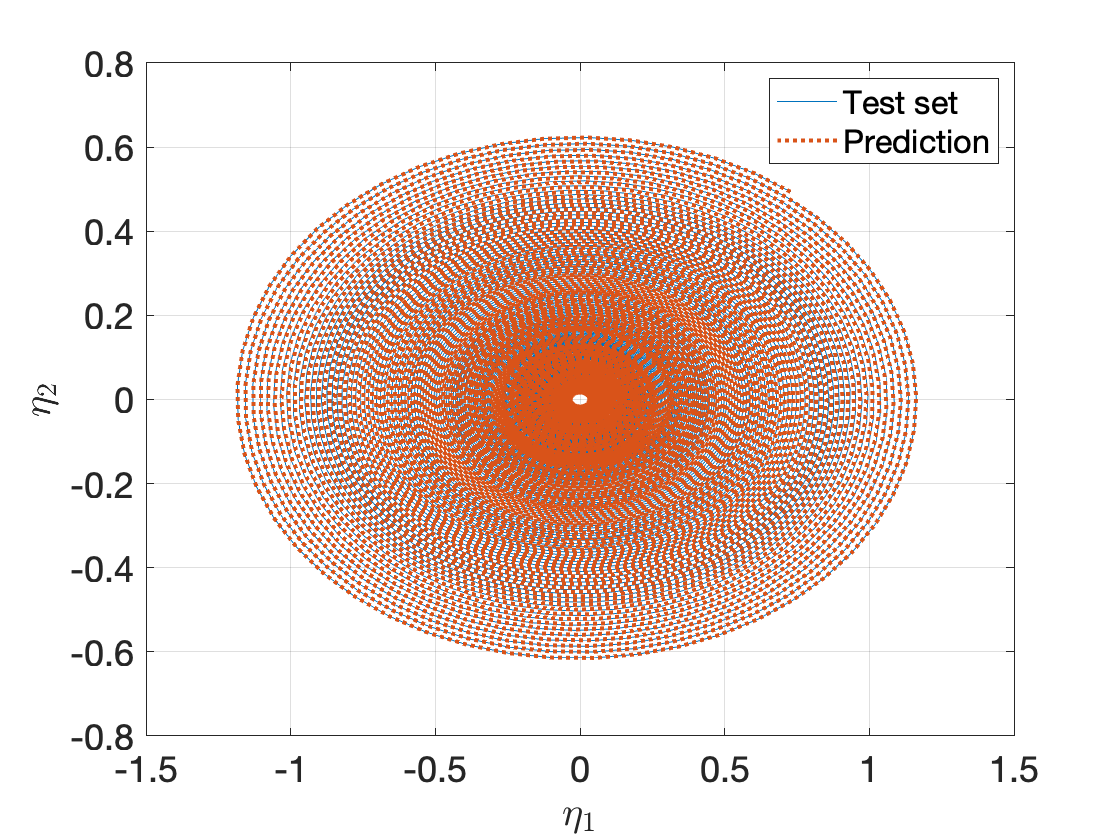


% Plot trajectories
plotReducedCoordinates(etaData(indTest,:), etaRec(indTest,:))
legend({'Test set', 'Prediction'})

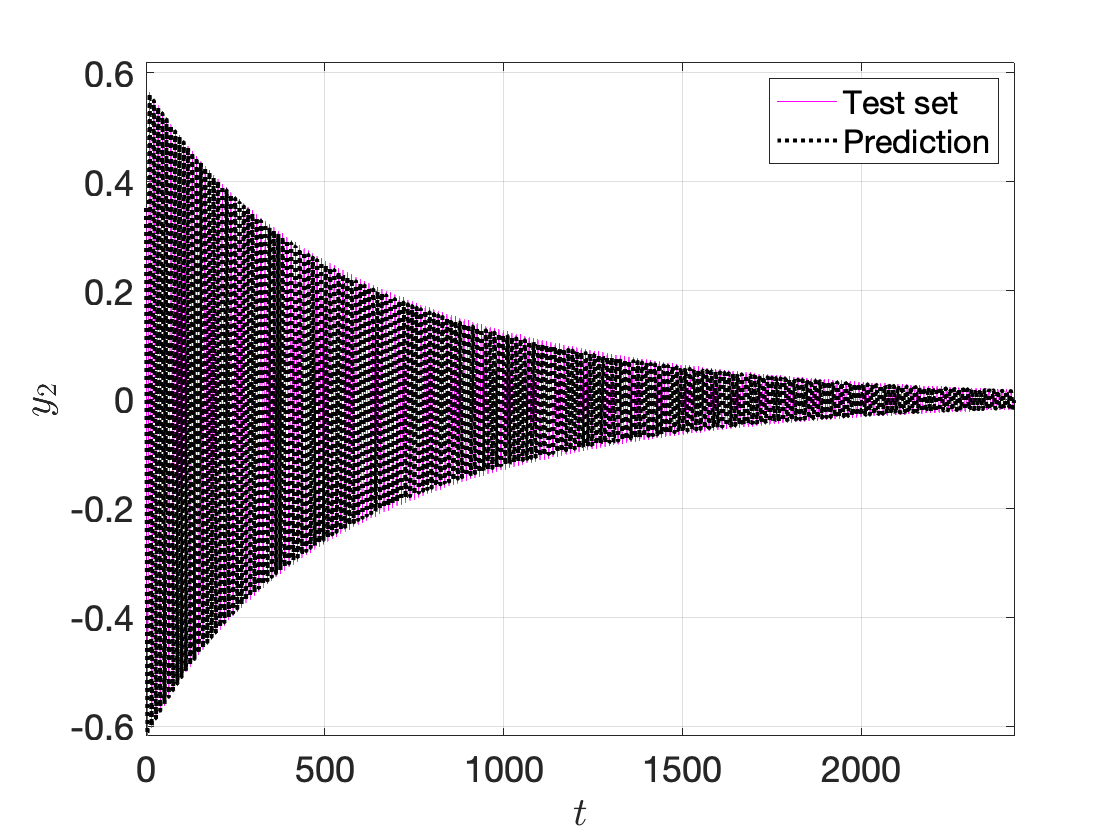

plotTrajectories(yData(indTest,:), yRec(indTest,:), 'm', fix(n/2), {'Test set', 'Prediction'})


% Check eigenvalues
reconstructedEigenvalues = RDInfo.eigenvaluesLinPartFlow;
[lambda(1) reconstructedEigenvalues(1)]

ans =   -0.0013 + 0.5176i  -0.0014 + 0.5177i


## Backbone curves and frequency responses

We can now study the reduced order model. We extract backbones curves and forced response curves (FRCs). For the latter, our 

$$\dot{z} =N(z) + f_{red} e^{i\Omega}$,

where $$\Omega$ is the forcing frequency and $$f_{red}$ is the forcing amplitude. For FRC extraction, we both use the analytical solution, that computes fixed points of the polar normal form with a closed form solution, and numerical continuation, via the continuation core coco.

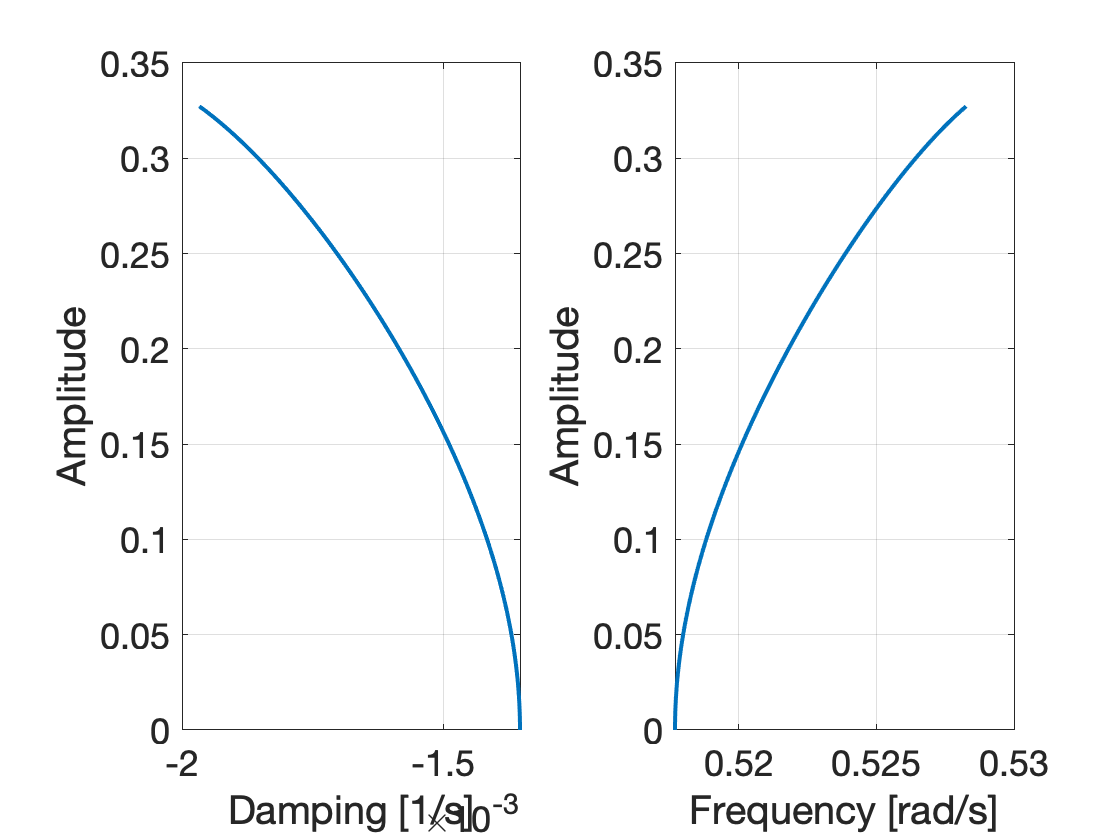

% Define the physical amplitude metric

amplitudeFunction = @(x) x(1,:); maxRho = max(abs(zRec{1,2}(1,:)));

% Compute backbone curves in the training range of data
BBCInfo = backboneCurves(IMInfo, RDInfo, amplitudeFunction,maxRho);


% Compute frequency response curves
omegaSpan = [0.95 1.05]*abs(reconstructedEigenvalues(1)); 
forcingSpan = [1 4 8]*1e-4; 
FRCData = analyticalFRC(IMInfo,RDInfo,forcingSpan,amplitudeFunction);
FRCDataCOCO = computeFRC(IMInfo,RDInfo,forcingSpan,omegaSpan,amplitudeFunction);

Frequency sweep for the forcing value number 1 ...

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          7.84e-05  2.56e+01    0.0    0.0    0.0
   1   1  1.00e+00  1.07e-04  7.53e-13  2.56e+01    0.0    0.0    0.0
   2   1  1.00e+00  4.05e-11  9.18e-18  2.56e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE     po.period            T
    0  00:00:00   2.5552e+01      1  EP      1.2776e+01   1.2776e+01
   10  00:00:00   2.4418e+01      2          1.2209e+01   1.2209e+01
   20  00:00:01   2.4331e+01      3          1.2165e+01   1.2165e+01
   30  00:00:01   2.4290e+01      4          1.2143e+01   1.2143e+01
   40  00:00:01   2.4261e+01      5          1.2128e+01   1.2128e+01
   50  00:00:02   2.4234e+01      6          1.2115e+01   1.2115e+01
   60  00:00:02   2.4193e+01      7          1.2096e+01   1.2096e+01
   70  00:00:02   2.4099e+01      8          

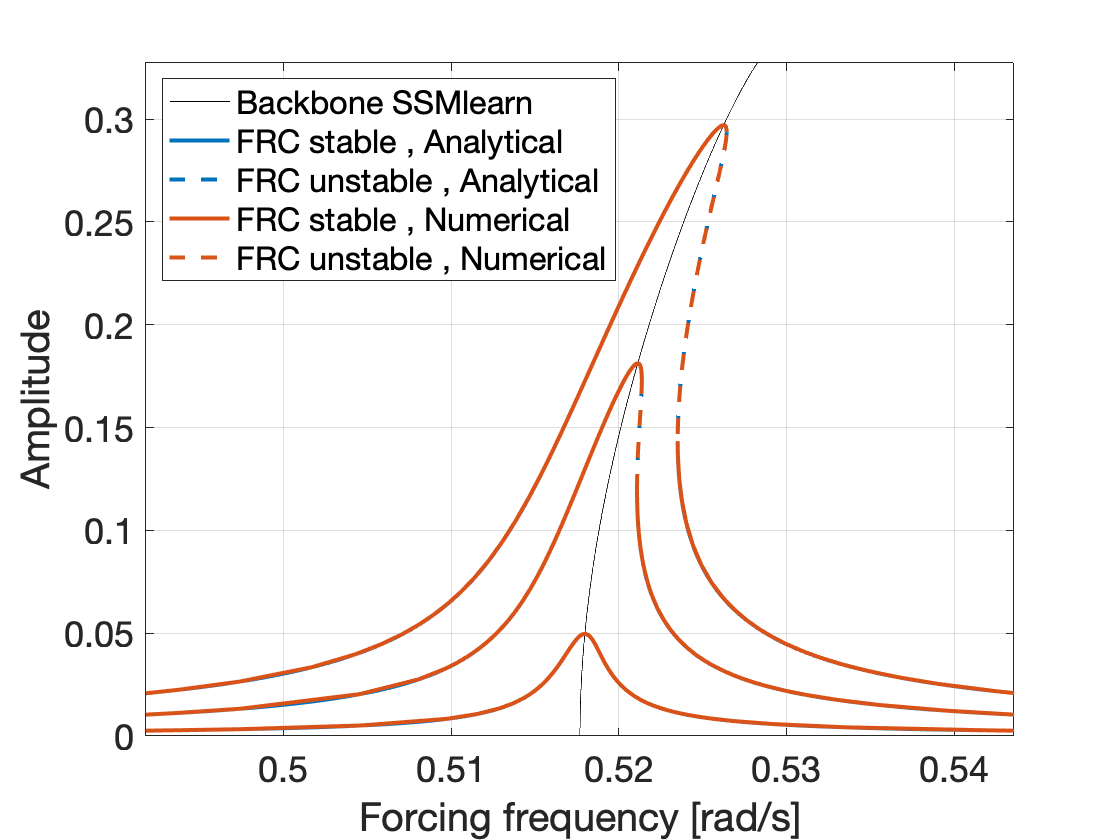


% Plot backbone curves and FRCs
customFigure(); colors = colororder;
plot(BBCInfo.frequency, BBCInfo.amplitude,'k','DisplayName', 'Backbone')
plotFRC(FRCData, colors(1,:), ', Analytical')
plotFRC(FRCDataCOCO, colors(2,:), ', Numerical')
xlim(omegaSpan)
ylim([0 max(BBCInfo.amplitude)])
legend('location','NW')